addpath(genpath('.'));
plotBoundaries = 1.1;

Define lines

coefficients = [3 -0.5 0];
q = [0.2 0.7 0.6];
pointsPerLine = 50;

Draw lines

figure
hold on
X = zeros(2, pointsPerLine * length(coefficients));
for i = 1:length(coefficients)
    range = (1 + (i-1) * pointsPerLine):(i * pointsPerLine);
    X(1, range) = (rand(1,pointsPerLine) - 0.5)*2;
    X(2, range) = coefficients(i) .* X(1, range) + q(i);
end
X(2, :) = X(2, :) / max(X(2, :));
for i = 1:length(coefficients)
    range = (1 + (i-1) * pointsPerLine):(i * pointsPerLine);
    scatter(X(1,range), X(2,range));
end

Algorithm starts

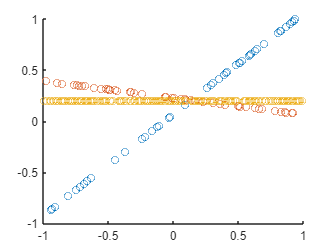

hold off

clusterSize = 10;
clusterThreshold = 25;
labelled_data = false;
numTotPoints = length(X);
nRealPoints = numTotPoints;
nOutliers = 0;
numToClusterizePoints = numTotPoints;    
nClusters = 3;
datasetTitle ="Lines3_15_O0";
pointsPerCluster = numTotPoints / nClusters;
G = generateGTLbls(nClusters, pointsPerCluster, nOutliers);

'generateGTLbls' is not found in the current folder or on the MATLAB path, but
exists in:
    C:\Users\locat\Documents\Uni\IACV\Code\IACVProject-MultiDendroCut\DataOperationFunctions

Change the MATLAB current folder or add its folder to the MATLAB path.

[distFun, hpFun, fit_model, cardmss, isMergeableGricModel] = set_model('line');

epsilonRange = 0.12; % An inlier threshold value epsilon has to be specified.

outlierRange = length(X); % consider all points

lambda1 = [];
lambda2 = [];
bestThresholds = [];

epsilon = epsilonRange(1);

%% Perform T-Linkage
[lblsTLinkage, T] = t_linkage(X, distFun, epsilon, cardmss, hpFun);

Now perform dynamic T-Linkage

tree = linkage_to_tree(T);
if length(epsilonRange) == 1
    printBranches(tree, X, max(tree(end,3)));
end

root = tree(end, 3);

lambdaRange = 0:5:60;
[bestLambda1, bestLambda2, bestThreshold] = computeBestParams(root, X, tree, G, lblsTLinkage, lambdaRange, ...
    isMergeableGricModel, epsilon);

%%
[~, ~, ~, ~, toMergeClusters] = exploreDFS(root, X, tree, bestLambda1, bestLambda2, epsilon, ...
    isMergeableGricModel, false);

lblsDynTLinkage = labelsAfterDynCut(X, tree, toMergeClusters, bestThreshold);

Dynamic T-Linkage ended, now perform improvement of what dyn T-Linkage provides


lambda1(end + 1) = bestLambda1;
lambda2(end + 1) = bestLambda2;
bestThresholds(end + 1) = bestThreshold;

%% Outlier rejection step

%T-Linkage fit a model to all the data points. Outlier can be found in
%different ways (T-Linkage is agonostic about the outlier rejection strategy),
%for example discarding too small cluster, or exploiting the randomness of
%a model.

lblsTLinkage = operateOnOutliers(lblsTLinkage, cardmss);
%lblsDynTLinkage = operateOnOutliers(lblsDynTLinkage, cardmss);


%% Order labels step
lblsTLinkage = orderClusterLabels(lblsTLinkage, clusterSize);
lblsDynTLinkage = orderClusterLabels(lblsDynTLinkage, clusterSize);

candidateOutliers = LOF(X');
lblsLOFDynCut = lblsDynTLinkage;
lblsLOFDynCut(candidateOutliers) = 0;

%% Showing results
if length(epsilonRange) == 1 && length(outlierRange) == 1
    figure('name','Assigned labels')
    s = subplot(1,3,1); gscatter(X(1,:),X(2,:), G); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('GroundTruth'); legend off
    s = subplot(1,3,2); gscatter(X(1,:),X(2,:), lblsTLinkage); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('T linkage'); legend off
    s = subplot(1,3,3); gscatter(X(1,:),X(2,:), lblsDynTLinkage); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('Dyn T linkage'); legend off
end

Here we do some comparison to ground truth, to compare the outcomes changing parameters

%% Compare clustering
tLinkageMetrics = compareClustering(G, lblsTLinkage);
dynTLinkageMetrics = compareClustering(G, lblsDynTLinkage);
%LOFdynTLinkageMetrics = compareClustering(G, lblsLOFDynCut);

%metrics(outlierIdx, eps).tLinkage = tLinkageMetrics;
%metrics(outlierIdx, eps).dynTLinkage = dynTLinkageMetrics;